# Análise de Fourier

clear all;
clc;
close all;



## Sinal em análise g(t)

To = 1                          % período

To = 1

fo = 1/To

fo = 1

wo = 2*pi*fo

wo = 6.2832


gt = @(t) (exp(-t))

gt = function_handle with value:
    @(t)(exp(-t))


## Análise de fourier

syms n t 

Dn = (1/To)*int(gt*exp(-j*n*wo*t),t,0,To)

$$Dn = -\frac{{\mathrm{e}}^{-1}\,{\mathrm{e}}^{-2\,\pi \,n\,\mathrm{i}}-1}{1+2\,\pi \,n\,\mathrm{i}}$$


N = 2;
n=[-N:1:N];

D =  eval(Dn)

D =    0.0040 + 0.0500i   0.0156 + 0.0981i   0.6321 + 0.0000i   0.0156 - 0.0981i   0.0040 - 0.0500i


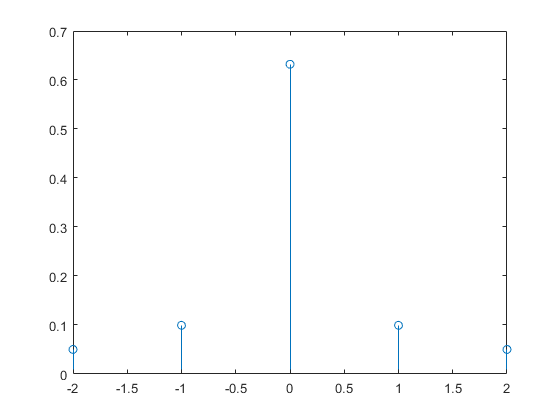


figure()

stem(n*fo,abs(D))

## Sintese de Fourier

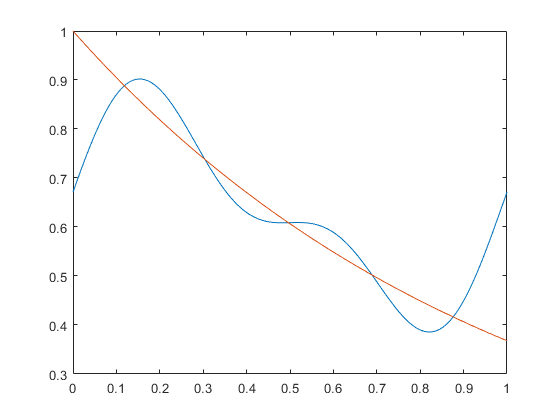


aux = 0;
tempo = [0:0.001:To];

for k=1:2*N+1
    
    aux = aux + D(k)*exp(j*n(k)*wo*tempo);
end

figure()

plot(tempo,aux,tempo,gt(tempo))